# Spline DEMO

Demonstrație cu spline cubice

Alegem funcția $f(x)=\cos x$ și nodurile $0,\pi/2, \pi, 3\pi/2, 2\pi$

f = @(x) cos(x);
d=-sin([0,2*pi]);
t=linspace(0,2*pi,200)';
x=[0,pi/2,pi,3*pi/2,2*pi]; y=f(x);

## Spline complete

c1 = CubicSplinec(x,y,0,d);
s1 = evalsplinec(x,c1,t);

## spline cu derivate secunde

d2 = -cos([0,2*pi]);
c2 = CubicSplinec(x,y,1,d2);
s2 = evalsplinec(x,c2,t);

## spline naturale

c3 = CubicSplinec(x,y,2);
s3 = evalsplinec(x,c3,t);

## spline deBoor

c4 = CubicSplinec(x,y,3);
s4 = evalsplinec(x,c4,t);

## reprezentare grafică

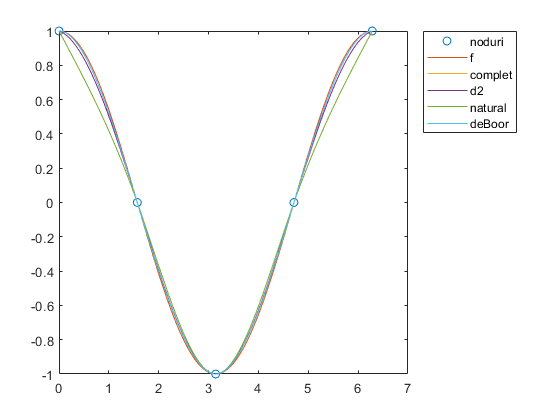

yg=f(t);
plot(x,y,'o',t,[yg,s1,s2,s3,s4])
legend('noduri','f','complet','d2','natural','deBoor','Location','BestOutside')